% Show Barker Autocorrelations search example
sequenceLength = 13;
hBCode = comm.BarkerCode('Length',7,'SamplesPerFrame', sequenceLength);
seq = step(hBCode);
gapLen = 100;
gapLenEnd = 200;
gen = @(Len) 2*randi([0 1],Len,1)-1;
y = [gen(gapLen); seq; gen(gapLenEnd)];
corr = xcorr(y,seq);
L = length(corr);
[v,i] = max(corr);

## Plot

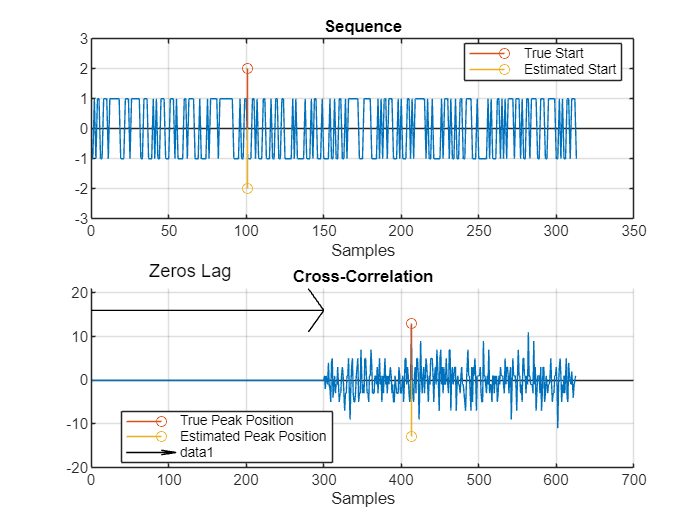

close all;
figure(1);
subplot(2,1,1);
h1 = plot(y);grid on;title('Sequence');xlabel('Samples');
hold on;
h2 = stem(gapLen+1,2);
hold off;
ylim([-3 3]);

subplot(2,1,2);title('Cross-Correlation');xlabel('Samples');
hold on;
h3 = plot(corr);grid on;
h6 = stem(i,v);
hold off;

% Estimation of peak position
% The correlation sequence should be 2*L-1, where L is the length of the
% longest of the two sequences
%
% The first N-M will be zeros, where N is the length of the long sequence
% and N is the length of the shorter sequence
%
% The peak itself will occur at zero lag, or when they are directly
% overlapping, resulting in a peak in the middle sample in correlation

numZeros = length(y) - sequenceLength;
fromSeqEdge = gapLen + sequenceLength;
peakPosEst = numZeros + fromSeqEdge;
hold on;
h4 = stem(peakPosEst,-v);
legend([h6,h4],'True Peak Position','Estimated Peak Position','Location','Best');
hold off;

% Estimate 'gapLen' with known BarkerLength and Number of starting zeros
[~,p] = max(corr);
numZeros = length(y) - sequenceLength;
estGapLen = p - numZeros - sequenceLength + 1;
subplot(2,1,1);
hold on;
h5 = stem(estGapLen,-2);
legend([h2 h5],'True Start','Estimated Start','Location','Best');
hold off;

% Draw offset
p1 = [0 v+3];
p2 = [numZeros v+3];
dp = p2-p1;
subplot(2,1,2);
hold on;
% Zeros Lag
h=quiver(p1(1),p1(2),dp(1),dp(2),0, 'Color','k');
text(dp(1)/4,25, 'Zeros Lag','FontSize',11)
hold off;